clear

## Load model and set physiological constraints

- AraCORE model 

- photoautotrophic growth

- unit: mol/gDW/d

model = readCbModel('Data/AraCORE_Arnold/ArabidopsisCoreModel.xml');
model.rxnGeneMat = zeros(length(model.rxns),length(model.genes));
for i=1:length(model.genes)
    for j=1:length(model.rxns)
        if ~isempty(strfind(model.rules{j},strcat('x(',num2str(i),')')))
            model.rxnGeneMat(j,i)=1;
        end
    end
end

%% bounds for photoautotrophic growth
bounds = readtable('Data/AraCORE_Arnold/AraCORE_photoautotrophic_bounds.csv');
model.lb = bounds{:,2};model.ub = bounds{:,3};
model.rev = zeros(size(model.rxns));
model.rev(model.lb<0) = 1;

model_irr = split_rxns(model);
model_irr.c(:) = 0;

model_irr.csense=repmat('E',size(model_irr.b));
lb_orig = model_irr.lb;
ub_orig = model_irr.ub;

%%
DIRECTION=ones(size(model_irr.rxns));
for i=1:length(model_irr.rxns)
    REV=strcmp(model_irr.rxns{i}(end-3:end),'_rev');
    if REV==1
        DIRECTION(i)=-1;
    end
end

[EC,~,IC] = unique(model_irr.rxnECNumbers);

Z=zeros(0,size(model_irr.S,2));
for i=1:length(EC)
    Z(end+1,IC==i) = DIRECTION(IC==i);
end

for i=1:length(EC)
    enzyme_gene_matrix(i,:)=max(model_irr.rxnGeneMat(IC==i,:),[],1);
end

%% for those with available abundance which EC have multiple rxns assigned
multiple_rxns=sum(Z')'>1;

for i=1:length(EC)
    id=find(Z(i,1:379)~=0); % exclude transport rxns, biomass
    
    comp_temp=[];
    for j=1:length(id)
        comp_temp{j}=model_irr.rxns{id(j)}(end);
    end
    Comp.names{i} = unique(comp_temp);
    Comp.number(i) = length(unique(comp_temp));
end

## Load Seaton/Sulpice et al. data

- end of day

- carbon-limiting growth photoperios 6-h, 8-h, optimal growth photoperiod 12-h, 18-h

- growth rate 0.11-0.31 gFW/gFW/d

### Abundance

- Abundance comes in units mol/gFW, we collect molecular weight from BRENDA to transform mol/gFW into mg/gFW

- no measured gDW/gFW we assume 0.088 gDW/gFW (Tschoep et al., 2009)

A = readtable('Data/Seaton_abundance/msb177962-sup-0003-tableev1_abundance.csv','Delimiter','\t');

protein_level=[19.0863 18.9733 18.2321 17.6531]; % mg protein/gFW

for s=1:4
    tot = sum(A{:,s+1},'omitnan');
    A{:,s+1} = A{:,s+1}/tot;
    mapECvalues=zeros(size(enzyme_gene_matrix));
    for i=1:length(model_irr.genes)
        id = find(strcmp(A.locus_id,model_irr.genes(i)));
        if ~isempty(id)
            mapECvalues(enzyme_gene_matrix(:,i)~=0,i) = sum(A{id,s+1},'omitnan');
        end
    end
    abundance_per_EC_mg_gFW_Seaton(:,s)=sum(mapECvalues,2).*protein_level(s);
    abundance_per_EC_mg_gFW_Seaton(abundance_per_EC_mg_gFW_Seaton==0) = nan;
end

### Enzyme activity

- 35 enzymes

temp_EA = readtable('Data/Sulpice_vmax/enzyme_activity.xlsx');


EA3.data=temp_EA{:,4:7}; % nmol/gFW/min  6,8,12,18-h

EA3.std=temp_EA{:,9:end};

EA3.data_lb = EA3.data - EA3.std;
EA3.data_ub = EA3.data + EA3.std;

EA3.EC=temp_EA.EC;
EA3.names=temp_EA.PhotoperiodMean;


### kcat estimated from v_max/E

kcat=readtable('Data/kcat_final_no_mutant.csv','Delimiter','\t'); % kcat BRENDA


idx = find(~isnan(max(abundance_per_EC_mg_gFW_Seaton,[],2,'omitnan')));

[EC_fit_Seaton,id_measured_Seaton,id_estimated_Seaton]=intersect(EC(idx),EA3.EC);

id_measured_Seaton=idx(id_measured_Seaton);

clear files
for f=1:length(EC_fit_Seaton)
    files(f,1)=strcat('MW_',strrep(EC_fit_Seaton(f),'.','_'),'.csv');
end
filesSeaton=files;

taxa=readtable('Data/taxaWB.csv','Delimiter','\t');

for f=1:length(files)
    temp = readtable(strcat('Data/MW/',files{f}),'Delimiter','\t');
    temp.Var9=nan(size(temp.Var8));
    Org = unique(temp{:,6});
    for o=1:length(Org)
        if ~isempty(find(strcmp(taxa.Var3,Org(o)))) && ~strcmp(Org(o),'')
            temp.Var9(strcmp(temp.Var6,Org(o)))=taxa.Var1(find(strcmp(taxa.Var3,Org(o))));
        end
    end
    temp.Var3(temp.Var3==-999)=nan;
    MW_mg_per_nmol_Seaton(f,1) = (median(temp.Var3(temp.Var9==min(temp.Var9,[],1,'omitnan')))*1000)/1e+9; % from Da to mg/nmol
end

E_measured3 = abundance_per_EC_mg_gFW_Seaton(id_measured_Seaton,:); % mg/gFW

for i=1:length(EC_fit_Seaton)
    if isempty(find(strcmp(kcat.EC,EC_fit_Seaton(i))))
        if ~isempty(strfind(EC_fit_Seaton{i},'/'))
            EC_temp=strsplit(EC_fit_Seaton{i},'/');
            kcat_temp=[]; t_temp=[];
            for j=1:length(EC_temp)
                kcat_temp=[kcat_temp; kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_temp(j))))];
                t_temp=[t_temp; kcat.tax_dist(find(strcmp(kcat.EC,EC_temp(j))))];
            end
            if ~isempty(kcat_temp)
                kcat_BRENDA_mean_Seaton(i,1) = mean(kcat_temp)*60;
                kcat_BRENDA_min_Seaton(i,1) = min(kcat_temp)*60;
                kcat_BRENDA_max_Seaton(i,1) = max(kcat_temp)*60;
                kcat_BRENDA_taxa(i,1) = max(t_temp);
            else
                kcat_BRENDA_mean_Seaton(i,1) = nan;
                kcat_BRENDA_min_Seaton(i,1) = nan;
                kcat_BRENDA_max_Seaton(i,1) = nan;
            end
        elseif ~isempty(strfind(EC_fit_Seaton{i},'+'))
            EC_temp=strsplit(EC_fit_Seaton{i},' + ');
            kcat_temp=[];t_temp=[];
            for j=1:length(EC_temp)
                kcat_temp=[kcat_temp; kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_temp(j))))];
                t_temp=[t_temp; kcat.tax_dist(find(strcmp(kcat.EC,EC_temp(j))))];
            end
            if ~isempty(kcat_temp)
                kcat_BRENDA_mean_Seaton(i,1) = mean(kcat_temp)*60;
                kcat_BRENDA_min_Seaton(i,1) = min(kcat_temp)*60;
                kcat_BRENDA_max_Seaton(i,1) = max(kcat_temp)*60;
                kcat_BRENDA_taxa(i,1) = max(t_temp);
            else
                kcat_BRENDA_mean_Seaton(i,1) = nan;
                kcat_BRENDA_min_Seaton(i,1) = nan;
                kcat_BRENDA_max_Seaton(i,1) = nan;
            end
        else
            kcat_BRENDA_mean_Seaton(i,1) = nan;
            kcat_BRENDA_max_Seaton(i,1) = nan;
            kcat_BRENDA_min_Seaton(i,1) = nan;
        end
    else
        kcat_BRENDA_mean_Seaton(i,1) = mean(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Seaton(i)))))*60;
        kcat_BRENDA_min_Seaton(i,1) = min(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Seaton(i)))))*60;
        kcat_BRENDA_median_Seaton(i,1) = median(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Seaton(i)))))*60;
        kcat_BRENDA_max_Seaton(i,1) = max(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Seaton(i)))))*60;
        kcat_BRENDA_taxa(i,1) = min(kcat.tax_dist(find(strcmp(kcat.EC,EC_fit_Seaton(i)))));
    end
end

kcat_BRENDA_max_Seaton(kcat_BRENDA_taxa>18)=nan;
kcat_BRENDA_min_Seaton(kcat_BRENDA_taxa>18)=nan;
kcat_BRENDA_mean_Seaton(kcat_BRENDA_taxa>18)=nan;
kcat_BRENDA_median_Seaton(kcat_BRENDA_taxa>18)=nan;

vmax_Seaton = EA3.data(id_estimated_Seaton,:).*repmat(MW_mg_per_nmol_Seaton,1,4); % nmol/gFW/min * mg/nmol = mg/gFW/min

kcat_estimated_vmax_Seaton = vmax_Seaton./E_measured3; % 1/min = mg/gFW/min / mg/gFW


## Load Piques et al. data

- end of day

- optimal growth

- growth rate 0.15-0.2 gFW/gFW/d

### Abundance

- Abundance comes in units mol/gFW, we collect molecular weight from BRENDA to transform mol/gFW into mg/gFW

- no measured gDW/gFW we assume 0.088 gDW/gFW (Tschoep et al., 2009)

A = readtable('Data/Piques_Data/abundance_msb200968-s7.csv','HeaderLines',3,'Delimiter','\t');

protein_level=15; % mg protein/gFW

tot = sum(A.Var7,'omitnan');
A.Var7 = A.Var7/tot;
mapECvalues=zeros(size(enzyme_gene_matrix));
for i=1:length(model_irr.genes)
    id = find(strcmp(A.Var3,model_irr.genes(i)));
    if ~isempty(id)
        mapECvalues(enzyme_gene_matrix(:,i)~=0,i) = sum(A.Var7(id),'omitnan');
    end
end
abundance_per_EC_mg_gFW_Piques=sum(mapECvalues,2).*protein_level;
abundance_per_EC_mg_gFW_Piques(abundance_per_EC_mg_gFW_Piques==0) = nan;

### Enzyme activity

- 35 enzymes

EA2.data=[443.7 114.9 874.1 3979.5 4026.4 4841.6 325.4 69.7 4010.5 ...
    184.9 4634.3 12987.1 54.5 321.6 794.4 2029.9 38.5 942.2 52544.7 ...
    1666.3 383.8 433.5 147.3 73.9 4087.8 981.2 60328.4 562.6 5568.7 440.3 ...
    1282.2 5034.8 84875.1 3804.2 3314.8]; % nmol/gFW/min  20h

% max all condition
% EA2.data=[523.2 230.1 874.1 5924.5 5608.6 5229.2 330.9 98.8 5691.9 278.6 ...
% 8967.3 18244.8 93.4 379.7 896.5 2199.8 51.8 1183.1 74631.0 1929.1 607.2 ...
% 633.9 178.5 176.4 5157.5 1128.0 67217.0 825.8 6841.7 576.7 1285.3 5868.1 ...
% 102880.5 4451.4 3689.2];

% mean all condition
% EA2.data=[454.9 162.8 719.8 4402.4 4559.0 4525.9 236.1 77.0 4332.3 212.5 ...
% 6812.0 14067.2 66.4 330.8 857.2 1939.6 41.1 877.1 55784.6 1671.9 459.5 ...
% 504.0 135.5 120.3 4485.9 1017.0 61611.5 646.0 6141.9 499.9 1070.3 5211.1 ...
% 85470.4 3534.1 3368.3];

EA2.std=[38.1 33.7 30.2 537.3 346.4 1179.1 0 23.1 179.5 23.8 517.7 2107.9 ...
    27.7 14.5 38.0 100.4 28.1 138.7 8869.4 185.9 21.2 92.2 65.5 42.1 351.4 ...
    52.4 346.0 163.2 269.8 52.6 316.7 512.4 3552.8 687.9 490.0];

EA2.data_lb = EA2.data - EA2.std;
EA2.data_ub = EA2.data + EA2.std;

EA2.EC={'3.2.1.26'
    '4.2.1.3'
    '2.7.7.27'
    '2.6.1.2'
    '2.6.1.1'
    '4.1.2.13'
    '2.7.1.4'
    '3.1.3.11'
    '4.2.1.2'
    '1.1.1.49'
    '1.2.1.13'
    '1.2.1.12'
    '2.7.1.1'
    '1.4.1.2'
    '6.3.1.2'
    '2.7.1.31'
    '1.1.1.41'
    '1.1.1.42'
    '1.1.1.37'
    '1.1.1.82'
    '1.7.1.1'
    '4.1.1.49'
    '2.7.1.11'
    '2.7.1.90'
    '5.4.2.2'
    '5.3.1.9'
    '2.7.2.3'
    '2.7.1.40'
    '4.1.1.39'
    '1.1.1.25'
    '2.4.1.14'
    '2.2.1.1'
    '5.3.1.1'
    '2.7.7.9'
    '1.4.7.1'};

% Acid Invertase (INV)
% Aconitase
% ADP-glucose pyrophosphorylase (AGPase)
% Alanine aminotransferase (AlaAT)
% Aspartate aminotransferase (AspAT)
% Fructose-bisphosphate aldolase (FBP-Aldolase)
% Fructokinanse (FK)
% Fructose-1.6-bisphosphatase. cytosolic (cytFBPase)
% Fumarase (FUM)
% Glucose-6-phosphate dehydrogenanse (G6PDH)
% nanDP-dependent glyceraldehyde 3-phosphate dehydrogenanse (nanDP-GAPDH)
% nanD-dependent glyceraldehyde 3-phosphate dehydrogenanse (nanD-GAPDH)
% Glucokinanse/Hexokinanse (HK)
% nanD-dependent glutamate dehydrogenanse (nanD-GDH)
% Glutamine synthetase (GS)
% Glycerate kinanse (GK)
% nanD-dependent isocitrate dehydrogenanse (nanD-IDH)
% nanDP-dependent Isocitrate dehydrogenanse (nanDP-IDH)
% nanD-dependent malate dehydrogenanse (nanD-MDH)
% nanDP-dependent malate dehydrogenanse (nanDP-MDH)
% Nitrate reductase (NR)
% Phosphoenolpyruvate carboxylase (PEP carboxylase)
% ATP-dependent phosphofructokinanse (PFK)
% Pyrophosphate-dependent phosphofructokinanse (PFP)
% Phosphoglucomutase (PGM)
% Glucose-6-phosphate isomerase (PGI)
% Phosphoglycerokinanse (PGK)
% Pyruvate kinanse (PK)
% Ribulose-1.5-bisphosphate carboxylase (RubisCO)
% Shikimate 5-dehydrogenanse (Shikimate DH)
% Sucrose phosphate synthase (SPS)
% Transketolase (TK)
% Triose phosphate isomerase (TPI)
% UDP-glucose pyrophosphorylase (UGPase)
% Ferredoxin-dependent glutamate synthase (Fd-GOGAT)

### kcat estimated from v_max/E

kcat=readtable('Data/kcat_final_no_mutant.csv','Delimiter','\t'); % kcat BRENDA


idx = find(~isnan(abundance_per_EC_mg_gFW_Piques));

[EC_fit_Piques,id_measured_Piques,id_estimated_Piques]=intersect(EC(idx),EA2.EC);

id_measured_Piques=idx(id_measured_Piques);

clear files
files(1).name='MW_1_1_1_25.csv';
files(2).name='MW_1_1_1_37.csv';
files(3).name='MW_1_1_1_41.csv';
files(4).name='MW_1_1_1_42.csv';
files(5).name='MW_1_1_1_82.csv';
files(6).name='MW_1_2_1_12.csv';
files(7).name='MW_1_2_1_13.csv';
files(8).name='MW_1_4_7_1.csv';
files(9).name='MW_1_7_1_1.csv';
files(10).name='MW_2_2_1_1.csv';
files(11).name='MW_2_4_1_14.csv';
files(12).name='MW_2_6_1_1.csv';
files(13).name='MW_2_6_1_2.csv';
files(14).name='MW_2_7_1_31.csv';
files(15).name='MW_2_7_1_40.csv';
files(16).name='MW_2_7_1_90.csv';
files(17).name='MW_2_7_2_3.csv';
files(18).name='MW_2_7_7_27.csv';
files(19).name='MW_2_7_7_9.csv';
files(20).name='MW_3_1_3_11.csv';
files(21).name='MW_4_1_1_39.csv';
files(22).name='MW_4_1_1_49.csv';
files(23).name='MW_4_1_2_13.csv';
files(24).name='MW_4_2_1_2.csv';
files(25).name='MW_4_2_1_3.csv';
files(26).name='MW_5_3_1_1.csv';
files(27).name='MW_5_3_1_9.csv';
files(28).name='MW_5_4_2_2.csv';
files(29).name='MW_6_3_1_2.csv';

files2=files;

taxa=readtable('Data/taxaWB.csv','Delimiter','\t');

for f=1:length(files)
    temp = readtable(strcat('Data/MW/',files(f).name),'Delimiter','\t');
    temp.Var9=nan(size(temp.Var8));
    Org = unique(temp{:,6});
    for o=1:length(Org)
        if ~isempty(find(strcmp(taxa.Var3,Org(o)))) && ~strcmp(Org(o),'')
            temp.Var9(strcmp(temp.Var6,Org(o)))=taxa.Var1(find(strcmp(taxa.Var3,Org(o))));
        end
    end
    temp.Var3(temp.Var3==-999)=nan;
    MW_mg_per_nmol_Piques(f,1) = (median(temp.Var3(temp.Var9==min(temp.Var9,[],1,'omitnan')))*1000)/1e+9; % from Da to mg/nmol
end

E_measured2 = abundance_per_EC_mg_gFW_Piques(id_measured_Piques); % mg/gFW

for i=1:length(EC_fit_Piques)
        if isempty(find(strcmp(kcat.EC,EC_fit_Piques(i))))
            if ~isempty(strfind(EC_fit_Piques{i},'/'))
            EC_temp=strsplit(EC_fit_Piques{i},'/');
            kcat_temp=[]; t_temp=[];
            for j=1:length(EC_temp)
                kcat_temp=[kcat_temp; kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_temp(j))))];
                t_temp=[t_temp; kcat.tax_dist(find(strcmp(kcat.EC,EC_temp(j))))];
            end
            if ~isempty(kcat_temp)
                kcat_BRENDA_mean_Piques(i,1) = mean(kcat_temp)*60;
                kcat_BRENDA_min_Piques(i,1) = min(kcat_temp)*60;
                kcat_BRENDA_max_Piques(i,1) = max(kcat_temp)*60;
                kcat_BRENDA_taxa_Piques(i,1) = max(t_temp);
            else
                kcat_BRENDA_mean_Piques(i,1) = nan;
                kcat_BRENDA_min_Piques(i,1) = nan;
                kcat_BRENDA_max_Piques(i,1) = nan;
            end
        elseif ~isempty(strfind(EC_fit_Piques{i},'+'))
            EC_temp=strsplit(EC_fit_Piques{i},' + ');
            kcat_temp=[];t_temp=[];
            for j=1:length(EC_temp)
                kcat_temp=[kcat_temp; kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_temp(j))))];
                t_temp=[t_temp; kcat.tax_dist(find(strcmp(kcat.EC,EC_temp(j))))];
            end
            if ~isempty(kcat_temp)
                kcat_BRENDA_mean_Piques(i,1) = mean(kcat_temp)*60;
                kcat_BRENDA_min_Piques(i,1) = min(kcat_temp)*60;
                kcat_BRENDA_max_Piques(i,1) = max(kcat_temp)*60;
                kcat_BRENDA_taxa_Piques(i,1) = max(t_temp);
            else
                kcat_BRENDA_mean_Piques(i,1) = nan;
                kcat_BRENDA_min_Piques(i,1) = nan;
                kcat_BRENDA_max_Piques(i,1) = nan;
            end
        else
            kcat_BRENDA_mean_Piques(i,1) = nan;
            kcat_BRENDA_max_Piques(i,1) = nan;
            kcat_BRENDA_min_Piques(i,1) = nan;
            end
        else
            kcat_BRENDA_mean_Piques(i,1) = mean(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Piques(i)))))*60;
            kcat_BRENDA_min_Piques(i,1) = min(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Piques(i)))))*60;
            kcat_BRENDA_median_Piques(i,1) = median(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Piques(i)))))*60;
            kcat_BRENDA_max_Piques(i,1) = max(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Piques(i)))))*60;
            kcat_BRENDA_taxa_Piques(i,1) = min(kcat.tax_dist(find(strcmp(kcat.EC,EC_fit_Piques(i)))));
        end
end

kcat_BRENDA_max_Piques(kcat_BRENDA_taxa_Piques>18)=nan;
kcat_BRENDA_min_Piques(kcat_BRENDA_taxa_Piques>18)=nan;
kcat_BRENDA_mean_Piques(kcat_BRENDA_taxa_Piques>18)=nan;
kcat_BRENDA_median_Piques(kcat_BRENDA_taxa_Piques>18)=nan;

vmax_Piques = EA2.data(id_estimated_Piques).*MW_mg_per_nmol_Piques'; % nmol/gFW/min * mg/nmol = mg/gFW/min

kcat_estimated_vmax_Piques = vmax_Piques./E_measured2'; % 1/min = mg/gFW/min / mg/gFW


## Load Pyl et al. data

- 5 different conditions (varying day/night temperature combinantions)

- samples from end of day

- carbon limiting growth

### Abundance

- abundance comes in units mol%, since the data do not sum up to 100% we first scale them to 100%

- we use respective measured mg protein/gFW and gDW/gFW to obtain units mg protein/gDW

A = readtable('Data/Pyl_Data/tpc097188SupplementalDS4.csv','HeaderLines',3,'Delimiter','\t');


protein_level=[20.84 17.91 13.43 12.91 12.91]; % mg protein/gFW Suppl. DataSet2
gDW_per_gFW=[109.9 98 87.5 88.2 88.1]/1000; % gDW/gFW
val = protein_level./gDW_per_gFW; % mg protein/gDW

for f=1:size(A,2)-1
    tot = sum(A{:,f+1});
    A{:,f+1} = A{:,f+1}/tot;
    mapECvalues=zeros(size(enzyme_gene_matrix));
    for i=1:length(model_irr.genes)
        id = find(strcmp(A.Genes,model_irr.genes(i)));
        if ~isempty(id)
            mapECvalues(enzyme_gene_matrix(:,i)~=0,i) = sum(A{id,f+1},'omitnan');
        end
    end
    abundance_per_EC_mg_gDW_Pyl(:,f)=sum(mapECvalues,2).*val(f);
    abundance_per_EC_mg_gFW_Pyl(:,f)=sum(mapECvalues,2).*protein_level(f);
end
abundance_per_EC_mg_gDW_Pyl(abundance_per_EC_mg_gDW_Pyl==0) = nan;
abundance_per_EC_mg_gFW_Pyl(abundance_per_EC_mg_gFW_Pyl==0) = nan;

### Enzyme activity

EA.data=[805	4010	741	1148	7817	7898	15270	1625	415	24698	980	184653	3450	756	1371	883	1254
    457	3673	614	1323	7136	7915	16461	1162	385	21380	742	156454	4000	473	1261	754	1016
    272	1979	453	1026	5916	6909	12411	986	262	19396	536	144729	4083	218	833	688	1106
    205	2384	618	1110	6382	7135	13231	748	295	18788	499	136787	3658	460	907	607	1098
    259	2988	785	1400	5751	7164	12799	904	321	17587	516	149877	3380	522	1043	616	787];
% nmol/gFW/min

EA.names={'nitrate reductase'	'alanine aminotrans-ferase'...
    'nanD-glutamate DH'	'glutamine synthetase'	'RubisCO (maximal)'...
    'trans- ketolase'	'nanDP- GAPDH'	'pyruvate kinanse'	'phospho-fructo- kinanse (ATP)'...
    'nanD- GAPDH'	'phospho-enolpyruvate carboxylase'	'nanD- malate DH'	'fumarase'...
    'sucrose phosphate synthase'	'phospho-gluco isomerase (cytosolic)'...
    'phospho-gluco isomerase (plastidial)'	'AGPase'};

EA.EC={'1.7.1.1' '2.6.1.2' '1.4.1.2' '6.3.1.2' '4.1.1.39' '2.2.1.1' '1.2.1.13' '2.7.1.40'...
    '2.7.1.1' '1.2.1.12' '4.1.1.49' '1.1.1.37' '4.2.1.2' '2.4.1.14' '5.3.1.9' '5.3.1.9'...
    '2.7.7.27'};

% {'nitrate reductase'; 181+182-183
%     'alanine aminotrans-ferase'; 191-192+193-194+195+196
%     'nanD-glutamate DH'; 233
%     'glutamine synthetase'; 239+240+241
%     'RubisCO (maximal)'; 7+113
%     'trans- ketolase'; 16-17+20-21
%     'nanDP- GAPDH'; 10+82
%     'pyruvate kinanse'; 91+92
%     'phospho-fructo- kinanse (ATP)'; 41
%     'nanD- GAPDH'; 80-81+85+86
%     'phospho-enolpyruvate carboxylase'; 71+72-73
%     'NAD- malate DH'; 69-70+106-107+125-126+148-149
%     'fumarase'; 105+206
%     'sucrose phosphate synthase'; 58
%     'phospho-gluco isomerase (cytosolic)'; 52-53
%     'phospho-gluco isomerase (plastidial)'; 27-28
%     'AGPase'} 31


## kcat eatimation from vmax/E


kcat=readtable('Data/kcat_final_no_mutant.csv','Delimiter','\t');


idx = find(~isnan(max(abundance_per_EC_mg_gDW_Pyl,[],2,'omitnan')));

[EC_fit_Pyl,id_measured_Pyl,id_estimated_Pyl]=intersect(EC(idx),EA.EC);

id_measured_Pyl=idx(id_measured_Pyl);

E_measured = abundance_per_EC_mg_gFW_Pyl(id_measured_Pyl,:);

for i=1:length(EC_fit_Pyl)
    kcat_BRENDA_mean_Pyl(i,1) = mean(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Pyl(i)))))*60;
    kcat_BRENDA_min_Pyl(i,1) = min(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Pyl(i)))))*60;
    kcat_BRENDA_median_Pyl(i,1) = median(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Pyl(i)))))*60;
    kcat_BRENDA_max_Pyl(i,1) = max(kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_fit_Pyl(i)))))*60;
    kcat_BRENDA_taxa_Pyl(i,1) = min(kcat.tax_dist(find(strcmp(kcat.EC,EC_fit_Pyl(i)))));
end

kcat_BRENDA_max_Pyl(kcat_BRENDA_taxa_Pyl>18)=nan;
kcat_BRENDA_min_Pyl(kcat_BRENDA_taxa_Pyl>18)=nan;
kcat_BRENDA_mean_Pyl(kcat_BRENDA_taxa_Pyl>18)=nan;
kcat_BRENDA_median_Pyl(kcat_BRENDA_taxa_Pyl>18)=nan;

clear files
files(1).name='MW_1_1_1_37.csv';
files(2).name='MW_1_2_1_12.csv';
files(3).name='MW_1_2_1_13.csv';
files(4).name='MW_2_2_1_1.csv';
files(5).name='MW_2_6_1_2.csv';
files(6).name='MW_2_7_7_27.csv';
files(7).name='MW_4_1_1_39.csv';
files(8).name='MW_6_3_1_2.csv';

taxa=readtable('Data/taxaWB.csv','Delimiter','\t');

for f=1:length(files)
    temp = readtable(strcat('Data/MW/',files(f).name),'Delimiter','\t');
    temp.Var9=nan(size(temp.Var8));
    Org = unique(temp{:,6});
    for o=1:length(Org)
        if ~isempty(find(strcmp(taxa.Var3,Org(o)))) && ~strcmp(Org(o),'')
            temp.Var9(strcmp(temp.Var6,Org(o)))=taxa.Var1(find(strcmp(taxa.Var3,Org(o))));
        end
    end
    temp.Var3(temp.Var3==-999)=nan;
    MW_mg_per_nmol_Pyl(f,1) = (median(temp.Var3(temp.Var9==min(temp.Var9,[],1,'omitnan')))*1000)/1e+9; % from Da to mg/nmol
end

vmax_Pyl = EA.data(:,id_estimated_Pyl).*repmat(MW_mg_per_nmol_Pyl',5,1); % nmol/gFW/min * mg/nmol = mg/gFW/min

kcat_estimated_Pyl = vmax_Pyl'./E_measured; % 1/min = mg/gFW/min / mg/gFW

# RESULT 2

# Correlation kcat form v_max and kcat from BRENDA

- should be low

[EC_u1,iu_EC1,iu_Piques]=intersect(EC,EC_fit_Piques);
[EC_u2,iu_EC2,iu_Pyl]=intersect(EC,EC_fit_Pyl);
[EC_u3,iu_EC3,iu_Seaton]=intersect(EC,EC_fit_Seaton);

kcat_estimated_vmax_combined_all=nan(length(EC),10);
kcat_estimated_vmax_combined_all(iu_EC2,1:5)=kcat_estimated_Pyl(iu_Pyl,:);
kcat_estimated_vmax_combined_all(iu_EC1,6)=kcat_estimated_vmax_Piques(iu_Piques)';
kcat_estimated_vmax_combined_all(iu_EC3,7:10)=kcat_estimated_vmax_Seaton(iu_Seaton,:);

kcat_estimated_vmax_combined_all_mean = mean(kcat_estimated_vmax_combined_all,2,"omitnan");
kcat_estimated_vmax_combined_all_mean=kcat_estimated_vmax_combined_all_mean/60;

kcat_BRENDA_mean_all=nan(length(EC),1);
kcat_BRENDA_mean_all(iu_EC2,1)=kcat_BRENDA_mean_Pyl(iu_Pyl);
kcat_BRENDA_mean_all(iu_EC1,1)=kcat_BRENDA_mean_Piques(iu_Piques);
kcat_BRENDA_mean_all(iu_EC3,1)=kcat_BRENDA_mean_Seaton(iu_Seaton);

kcat_BRENDA_min_all=nan(length(EC),1);
kcat_BRENDA_min_all(iu_EC2,1)=kcat_BRENDA_min_Pyl(iu_Pyl);
kcat_BRENDA_min_all(iu_EC1,1)=kcat_BRENDA_min_Piques(iu_Piques);
kcat_BRENDA_min_all(iu_EC3,1)=kcat_BRENDA_min_Seaton(iu_Seaton);

kcat_BRENDA_max_all=nan(length(EC),1);
kcat_BRENDA_max_all(iu_EC2,1)=kcat_BRENDA_max_Pyl(iu_Pyl);
kcat_BRENDA_max_all(iu_EC1,1)=kcat_BRENDA_max_Piques(iu_Piques);
kcat_BRENDA_max_all(iu_EC3,1)=kcat_BRENDA_max_Seaton(iu_Seaton);

kcat_BRENDA_mean_all=kcat_BRENDA_mean_all/60;
kcat_BRENDA_min_all=kcat_BRENDA_min_all/60;
kcat_BRENDA_max_all=kcat_BRENDA_max_all/60;

save('Result2_kcat_from_vmax_from_BRENDA.mat')
disp('Number of enzymes:')

Number of enzymes:


length(intersect(find(~isnan(kcat_BRENDA_max_all)),find(~isnan(kcat_estimated_vmax_combined_all_mean))))

ans = 23


disp('Correlation kapp to mean kcat:')

Correlation kapp to mean kcat:


[C,P]=corr(log(kcat_BRENDA_mean_all),log(kcat_estimated_vmax_combined_all_mean),'rows','pairwise')

C = 0.5112

P = 0.0127

disp('Correlation kapp to min kcat:')

Correlation kapp to min kcat:


[C,P]=corr(log(kcat_BRENDA_min_all(kcat_BRENDA_min_all>0)),log(kcat_estimated_vmax_combined_all_mean(kcat_BRENDA_min_all>0)),'rows','pairwise')

C = 0.1471

P = 0.5030

disp('Correlation kapp to max kcat:')

Correlation kapp to max kcat:


[C,P]=corr(log(kcat_BRENDA_max_all),log(kcat_estimated_vmax_combined_all_mean),'rows','pairwise')

C = 0.5332

P = 0.0088

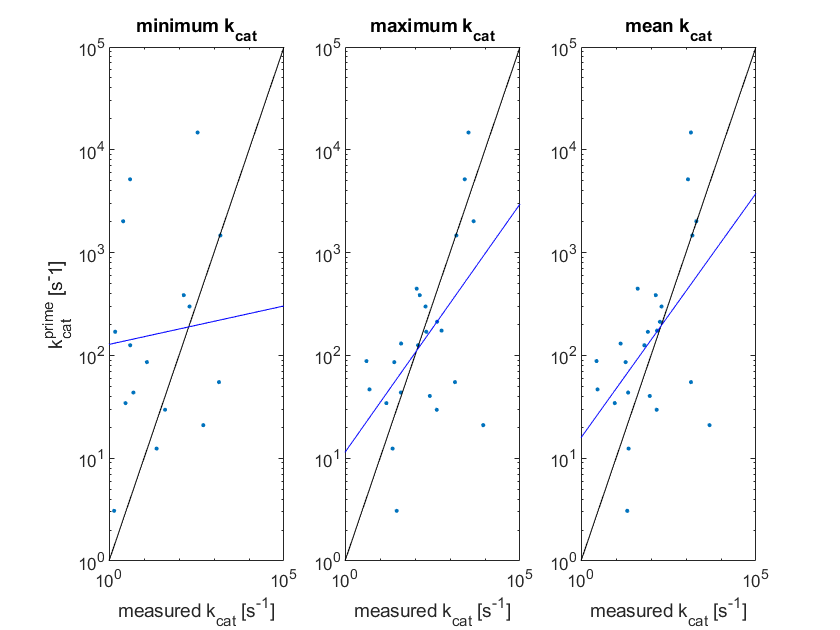

figure
subplot(1,3,3)
plot(kcat_BRENDA_mean_all,kcat_estimated_vmax_combined_all_mean,'.')
% ylabel('kcat estimated from v_{max} [1/s]')
xlabel('measured k_{cat} [s^{-1}]')
title('mean k_{cat}')
set(gca,'XScale','Log','YScale','Log')
xlim([1e0 1e5])
ylim([1e0 1e5])
hold on
plot([1e0 1e5],[1e0 1e5],'k')
hold on
[~,m,b]=regression(log(kcat_BRENDA_mean_all)',log(kcat_estimated_vmax_combined_all_mean)');
x=log([1e0; 1e1; 1e2;1e3;1e4;1e5]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')

subplot(1,3,1)
plot(kcat_BRENDA_min_all,kcat_estimated_vmax_combined_all_mean,'.')
% ylabel('kcat estimated from v_{max} [1/s]')
xlabel('measured k_{cat} [s^{-1}]')
title('minimum k_{cat}')
ylabel('k_{cat}^{prime} [s^-1]')
set(gca,'XScale','Log','YScale','Log')
xlim([1e0 1e5])
ylim([1e0 1e5])
hold on
plot([1e0 1e5],[1e0 1e5],'k')
hold on
[~,m,b]=regression(log(kcat_BRENDA_min_all)',log(kcat_estimated_vmax_combined_all_mean)');
x=log([1e0; 1e1; 1e2;1e3;1e4;1e5]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')

subplot(1,3,2)
plot(kcat_BRENDA_max_all,kcat_estimated_vmax_combined_all_mean,'.')
xlabel('measured k_{cat} [s^{-1}]')
set(gca,'XScale','Log','YScale','Log')
title('maximum k_{cat}')
xlim([1e0 1e5])
ylim([1e0 1e5])
hold on
plot([1e0 1e5],[1e0 1e5],'k')
hold on
[~,m,b]=regression(log(kcat_BRENDA_max_all)',log(kcat_estimated_vmax_combined_all_mean)');
x=log([1e0; 1e1; 1e2;1e3;1e4;1e5]);
y=(m.*x)+b;
plot(exp(x),exp(y),'-b')